## Sensory Adaptation of units to repeated whisker deflections

See [https://molecularautism.biomedcentral.com/articles/10.1186/s13229-021-00435-9](https://molecularautism.biomedcentral.com/articles/10.1186/s13229-021-00435-9) for a similar idea but EEG + humans with autism.

Load all_data struct and associated metadata from SfN_Emx > Whisker first.

%% Loading stuff and things

unit_data = all_data.No_CTZ.veh_3062_1.cid127;

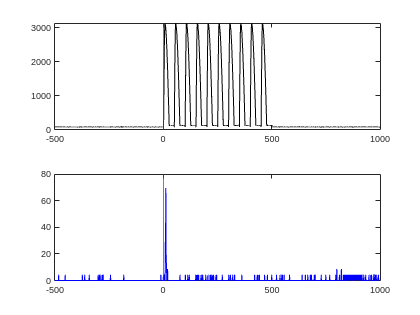

unitPSTH = unit_data.PSTHs_raw(end,:);

figure;
T = tiledlayout(2,1);

nexttile(T);
plot(relative_time_samples/30, StimVoltageTrace, 'Color','black');
xline(0, 'Color','red');

nexttile(T);
plot(relative_time_ms, unitPSTH, 'Color','blue');
xline(0, 'Color','red');

## Method 1

Get the two highest peaks in the first 150 ms, then calculate the peak1/peak2 ratio.

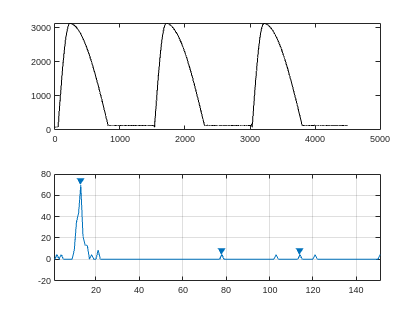

unitPSTH_peaksWin = unitPSTH((relative_time_ms >= 0)&(relative_time_ms <= 150));

figure;
T = tiledlayout(2,1);

nexttile(T);
plot(StimVoltageTrace((relative_time_samples >= 0)&(relative_time_samples <= 150*30)), 'Color','black');

nexttile(T);
findpeaks(unitPSTH_peaksWin, 'MinPeakDistance',25)

## Method 2

% definition: response to deflection 1 = first peak from 6 ms to 50 ms;
% response to deflection 2 = first peak from 56 to 100 ms; and so on.
% Normalize each subsequent response to the first peak.

PeakEvokedFR = unit_data.PeakEvokedFR(end);
NormalizedPeakFRs = zeros(10,1);
for deflectionNum = 1:10
    start_ms = 50*(deflectionNum-1) + 4;
    %end_ms = 50*deflectionNum;
    end_ms = start_ms+20; % doing 20 ms windows to be consistent with how the first peak was found

    start_ind = find(relative_time_ms == start_ms);
    end_ind = find(relative_time_ms == end_ms);

    NormalizedPeakFRs(deflectionNum) = max(unitPSTH(start_ind:end_ind)) / PeakEvokedFR;
end